pressures = [0 5 10 15 20 25 30 35 40 45 50 60 65 70 80];
lengths = [44.3 43.4 42.2 41.5 40.0 38.7 37.8 37.1 36.4 36.2 35.8 35.3 34.9 34.7 34.3] / 100;

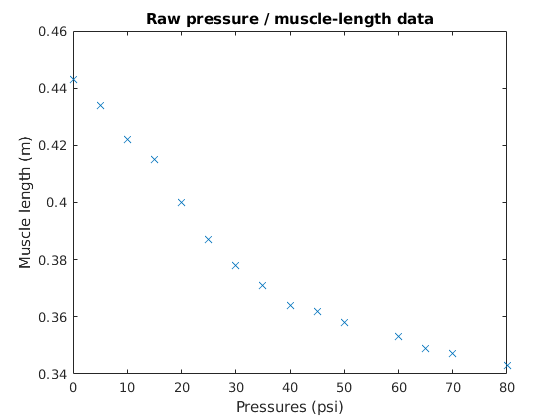

figure()
plot(pressures, lengths, 'x')
title("Raw pressure / muscle-length data")
xlabel("Pressures (psi)")
ylabel("Muscle length (m)")

% Fit:
fit_obj = fittype("l_max + a*exp(-b*x)")

fit_obj =      General model:
     fit_obj(a,b,l_max,x) = l_max + a*exp(-b*x)

fit_results = fit(pressures(:), lengths(:), fit_obj) % Start point is optional

fit_results =      General model:
     fit_results(x) = l_max + a*exp(-b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1198  (0.1096, 0.1299)
       b =     0.02748  (0.02126, 0.0337)
       l_max =      0.3283  (0.3169, 0.3398)

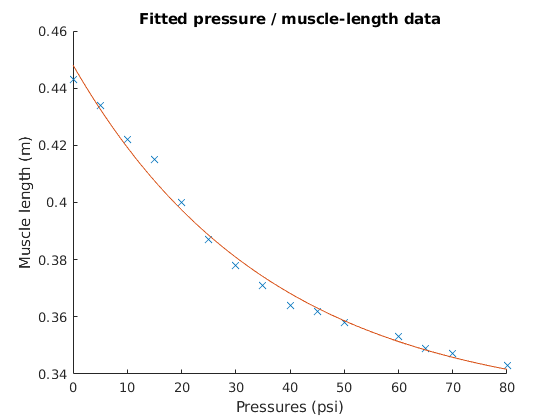

figure()
hold on
plot(pressures, lengths, 'x')

t_pressures = linspace(pressures(1), pressures(end));
plot(t_pressures, fit_results(t_pressures));

title("Fitted pressure / muscle-length data")
xlabel("Pressures (psi)")
ylabel("Muscle length (m)")

% Create symbolic expression for the fit
syms p
sym_fit = fit_results.l_max + fit_results.a * exp(-fit_results.b * p);

% Save the symbolic expression as a Matlab function file in the
% include/utils directory
matlabFunction(sym_fit, "File", "include/utils/contraction_fit");